# SOLUTION OF EXAMPLE EXERCISES

## EX1 - 2 masses connected by springs

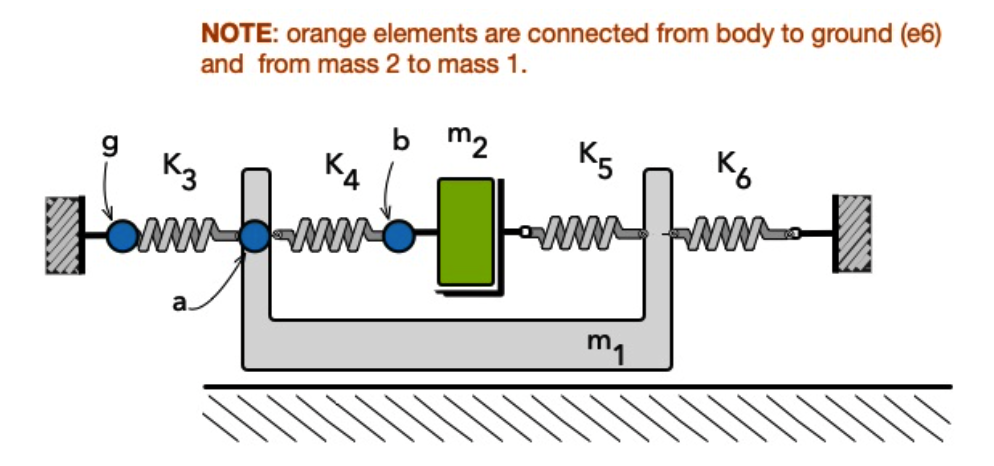

Equivalent system representation:

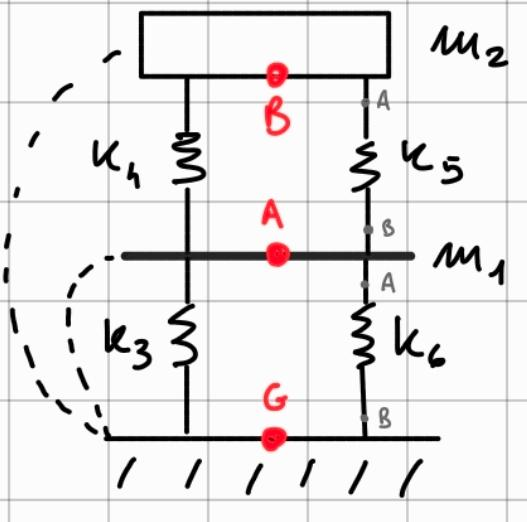

Linear Graph:

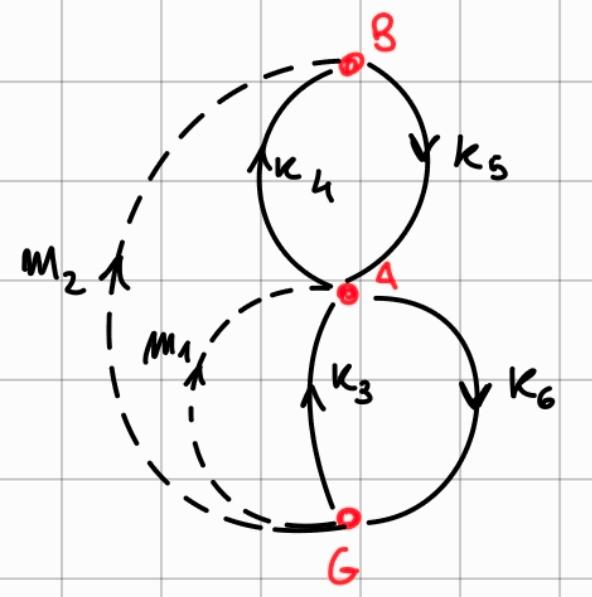

**Elements:**

- 4 mechanical springs (T-Type) --> 4 edges

- 2 masses (A-Type) --> 2 edges

### Definitions

clear; clc; close all;
addpath('MBLibs\')

% Define the system variables (through and across for each element)
syms t

N = 6; % Num of edges

% Through variables
syms v_m1(t) v_m2(t) x_k3(t) x_k4(t) x_k5(t) x_k6(t)
%                em1     em2     ek3     ek4     ek5     ek6
tau_vars =      [v_m1(t) v_m2(t) x_k3(t) x_k4(t) x_k5(t) x_k6(t)].';

% Across variables
syms F_m1(t) F_m2(t) F_k3(t) F_k4(t) F_k5(t) F_k6(t)
%                em1     em2     ek3     ek4     ek5     ek6
alpha_vars =    [F_m1(t) F_m2(t) F_k3(t) F_k4(t) F_k5(t) F_k6(t)].';

% CHECK: length of arrays is the same

### Constitutive equations

for each element (edge of the LG)

% Const. equations vector
% N.B. DIFFERENTIAL FIRST, algebraic later

syms m1 m2 k3 k4 k5 k6 % physical (constant) parameters

eqns_const = [
    % mass m1
    diff(v_m1,t) == 1/m1*F_m1(t);  % d/dt(v_m1) = F_m1(t)/m1
    % mass m2
    diff(v_m2,t) == 1/m2*F_m2(t);
    % spring k3
    F_k3(t) == k3*x_k3(t);
    % spring k4
    F_k4(t) == k4*x_k4(t);
    % spring k5
    F_k5(t) == k5*x_k5(t);
    % spring k6
    F_k6(t) == k6*x_k6(t)
    ]

$$eqns\_const(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}v_{\mathrm{m1}}\left(t\right)=\frac{F_{\mathrm{m1}}\left(t\right)}{m_{1}}\\ \frac{\partial }{\partial t}v_{\mathrm{m2}}\left(t\right)=\frac{F_{\mathrm{m2}}\left(t\right)}{m_{2}}\\ F_{\mathrm{k3}}\left(t\right)=k_{3}\,x_{\mathrm{k3}}\left(t\right)\\ F_{\mathrm{k4}}\left(t\right)=k_{4}\,x_{\mathrm{k4}}\left(t\right)\\ F_{\mathrm{k5}}\left(t\right)=k_{5}\,x_{\mathrm{k5}}\left(t\right)\\ F_{\mathrm{k6}}\left(t\right)=k_{6}\,x_{\mathrm{k6}}\left(t\right) \end{array}\right)$$


size(eqns_const)

ans =      1     1


### Loop and node equations

#### Incidence matrix

% Write it directly without singular rows (e.g. LIN DEP)
IM = [
    1 0 1 -1 1 -1;...
    0 1 0 1 -1 0;...
    1 1 1 0 0 -1
]

IM =      1     0     1    -1     1    -1
     0     1     0     1    -1     0
     1     1     1     0     0    -1



% Number of nodes and edges
[nn, ne] = size(IM);

rref(IM)

ans =      1     0     1    -1     1    -1
     0     1     0     1    -1     0
     0     0     0     0     0     0


% Number of nonsingular rows
nnsr = nn - rank(IM);

% Number of elements, branches, chords
nb = nn-nnsr;
nc = ne - nb;

A matrix

% A matrix
A = sym(IM(1:nb, 1:ne))

$$A = \left(\begin{array}{cccccc} 1 & 0 & 1 & -1 & 1 & -1\\ 0 & 1 & 0 & 1 & -1 & 0 \end{array}\right)$$

% Af and Ac as Af = [Ib | Ac]
Af = rref(A)

$$Af = \left(\begin{array}{cccccc} 1 & 0 & 1 & -1 & 1 & -1\\ 0 & 1 & 0 & 1 & -1 & 0 \end{array}\right)$$


Ac = Af(:, nb+1:end)

$$Ac = \left(\begin{array}{cccc} 1 & -1 & 1 & -1\\ 0 & 1 & -1 & 0 \end{array}\right)$$

B matrix

Bf = null(Af).'

$$Bf = \left(\begin{array}{cccccc} -1 & 0 & 1 & 0 & 0 & 0\\ 1 & -1 & 0 & 1 & 0 & 0\\ -1 & 1 & 0 & 0 & 1 & 0\\ 1 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$


% CHECK: Af*Bf' --> all zeros matrix

Bb = -Ac'

$$Bb = \left(\begin{array}{cc} -1 & 0\\ 1 & -1\\ -1 & 1\\ 1 & 0 \end{array}\right)$$

#### Node equations (Newton @ nodes)

node_eqns = tau_vars(1:nb) == -Ac * tau_vars(nb+1:ne)

$$node\_eqns = \left(\begin{array}{c} v_{\mathrm{m1}}\left(t\right)=x_{\mathrm{k4}}\left(t\right)-x_{\mathrm{k3}}\left(t\right)-x_{\mathrm{k5}}\left(t\right)+x_{\mathrm{k6}}\left(t\right)\\ v_{\mathrm{m2}}\left(t\right)=x_{\mathrm{k5}}\left(t\right)-x_{\mathrm{k4}}\left(t\right) \end{array}\right)$$

#### Circuit/Loop equations

loop_eqns = alpha_vars(nb+1:ne) == -Bb * alpha_vars(1:nb)

$$loop\_eqns = \left(\begin{array}{c} F_{\mathrm{k3}}\left(t\right)=F_{\mathrm{m1}}\left(t\right)\\ F_{\mathrm{k4}}\left(t\right)=F_{\mathrm{m2}}\left(t\right)-F_{\mathrm{m1}}\left(t\right)\\ F_{\mathrm{k5}}\left(t\right)=F_{\mathrm{m1}}\left(t\right)-F_{\mathrm{m2}}\left(t\right)\\ F_{\mathrm{k6}}\left(t\right)=-F_{\mathrm{m1}}\left(t\right) \end{array}\right)$$

### DAE system of equations

#### Dependent and independent coordinates

% DEPENDENT --> set of Chord Across coords and Through Branch coords
qvars_d = [lhs(node_eqns); lhs(loop_eqns)]

$$qvars\_d = \left(\begin{array}{c} v_{\mathrm{m1}}\left(t\right)\\ v_{\mathrm{m2}}\left(t\right)\\ F_{\mathrm{k3}}\left(t\right)\\ F_{\mathrm{k4}}\left(t\right)\\ F_{\mathrm{k5}}\left(t\right)\\ F_{\mathrm{k6}}\left(t\right) \end{array}\right)$$


% INDEPENDENT --> rest of the vars
allvars = [alpha_vars; tau_vars];
dae_vars = setdiff(allvars, qvars_d)

$$dae\_vars = \left(\begin{array}{c} F_{\mathrm{m1}}\left(t\right)\\ F_{\mathrm{m2}}\left(t\right)\\ x_{\mathrm{k3}}\left(t\right)\\ x_{\mathrm{k4}}\left(t\right)\\ x_{\mathrm{k5}}\left(t\right)\\ x_{\mathrm{k6}}\left(t\right) \end{array}\right)$$

#### Assembling and solving equations

% Subs loop equations into constitutive equations
tmp = subs(eqns_const, lhs(loop_eqns), rhs(loop_eqns));
% Then subs node equations into constitutive equations
dae_eqns = subs(tmp, lhs(node_eqns), rhs(node_eqns))

$$dae\_eqns(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{\mathrm{k4}}\left(t\right)-\frac{\partial }{\partial t}x_{\mathrm{k3}}\left(t\right)-\frac{\partial }{\partial t}x_{\mathrm{k5}}\left(t\right)+\frac{\partial }{\partial t}x_{\mathrm{k6}}\left(t\right)=\frac{F_{\mathrm{m1}}\left(t\right)}{m_{1}}\\ \frac{\partial }{\partial t}x_{\mathrm{k5}}\left(t\right)-\frac{\partial }{\partial t}x_{\mathrm{k4}}\left(t\right)=\frac{F_{\mathrm{m2}}\left(t\right)}{m_{2}}\\ F_{\mathrm{m1}}\left(t\right)=k_{3}\,x_{\mathrm{k3}}\left(t\right)\\ F_{\mathrm{m2}}\left(t\right)-F_{\mathrm{m1}}\left(t\right)=k_{4}\,x_{\mathrm{k4}}\left(t\right)\\ F_{\mathrm{m1}}\left(t\right)-F_{\mathrm{m2}}\left(t\right)=k_{5}\,x_{\mathrm{k5}}\left(t\right)\\ -F_{\mathrm{m1}}\left(t\right)=k_{6}\,x_{\mathrm{k6}}\left(t\right) \end{array}\right)$$


% CHECKS:
~(length(qvars_d)==N)

ans = logical
   0


% ~(length(eqns_const)==N)
% ~(length(dae_eqns)==length(dae_vars))

#### Equations manipulation: index reduction

[E_mat, G_mat] = massMatrixForm(dae_eqns, dae_vars)

$$E\_mat = \left(\begin{array}{cccccc} 0 & 0 & -1 & 1 & -1 & 1\\ 0 & 0 & 0 & -1 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$G\_mat = \left(\begin{array}{c} \frac{F_{\mathrm{m1}}\left(t\right)}{m_{1}}\\ \frac{F_{\mathrm{m2}}\left(t\right)}{m_{2}}\\ k_{3}\,x_{\mathrm{k3}}\left(t\right)-F_{\mathrm{m1}}\left(t\right)\\ F_{\mathrm{m1}}\left(t\right)-F_{\mathrm{m2}}\left(t\right)+k_{4}\,x_{\mathrm{k4}}\left(t\right)\\ F_{\mathrm{m2}}\left(t\right)-F_{\mathrm{m1}}\left(t\right)+k_{5}\,x_{\mathrm{k5}}\left(t\right)\\ F_{\mathrm{m1}}\left(t\right)+k_{6}\,x_{\mathrm{k6}}\left(t\right) \end{array}\right)$$

Dulmage-Mendelsohn to reorder equations

[p,q,~,~,~,~] = dmperm(double(E_mat));  % Only need p and q aka row and col permutation vectors
                                        % such that E_mat is in block diagonal form
E_sorted = E_mat(p, :) % Only change equation order

$$E\_sorted = \left(\begin{array}{cccccc} 0 & 0 & -1 & 1 & -1 & 1\\ 0 & 0 & 0 & -1 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

G_sorted = G_mat(p)

$$G\_sorted = \left(\begin{array}{c} \frac{F_{\mathrm{m1}}\left(t\right)}{m_{1}}\\ \frac{F_{\mathrm{m2}}\left(t\right)}{m_{2}}\\ k_{3}\,x_{\mathrm{k3}}\left(t\right)-F_{\mathrm{m1}}\left(t\right)\\ F_{\mathrm{m1}}\left(t\right)-F_{\mathrm{m2}}\left(t\right)+k_{4}\,x_{\mathrm{k4}}\left(t\right)\\ F_{\mathrm{m2}}\left(t\right)-F_{\mathrm{m1}}\left(t\right)+k_{5}\,x_{\mathrm{k5}}\left(t\right)\\ F_{\mathrm{m1}}\left(t\right)+k_{6}\,x_{\mathrm{k6}}\left(t\right) \end{array}\right)$$


% Number of differential equations in the system = rank(E_sorted)
n_ode = rank(E_sorted)

n_ode = 2

Sorted set of equations

eqns_sorted = E_sorted * diff(dae_vars,t) == G_sorted

$$eqns\_sorted = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{\mathrm{k4}}\left(t\right)-\frac{\partial }{\partial t}x_{\mathrm{k3}}\left(t\right)-\frac{\partial }{\partial t}x_{\mathrm{k5}}\left(t\right)+\frac{\partial }{\partial t}x_{\mathrm{k6}}\left(t\right)=\frac{F_{\mathrm{m1}}\left(t\right)}{m_{1}}\\ \frac{\partial }{\partial t}x_{\mathrm{k5}}\left(t\right)-\frac{\partial }{\partial t}x_{\mathrm{k4}}\left(t\right)=\frac{F_{\mathrm{m2}}\left(t\right)}{m_{2}}\\ 0=k_{3}\,x_{\mathrm{k3}}\left(t\right)-F_{\mathrm{m1}}\left(t\right)\\ 0=F_{\mathrm{m1}}\left(t\right)-F_{\mathrm{m2}}\left(t\right)+k_{4}\,x_{\mathrm{k4}}\left(t\right)\\ 0=F_{\mathrm{m2}}\left(t\right)-F_{\mathrm{m1}}\left(t\right)+k_{5}\,x_{\mathrm{k5}}\left(t\right)\\ 0=F_{\mathrm{m1}}\left(t\right)+k_{6}\,x_{\mathrm{k6}}\left(t\right) \end{array}\right)$$

ODE equations and variables

% Extract ODEs
ode_eqns = eqns_sorted(1:n_ode)

$$ode\_eqns = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{\mathrm{k4}}\left(t\right)-\frac{\partial }{\partial t}x_{\mathrm{k3}}\left(t\right)-\frac{\partial }{\partial t}x_{\mathrm{k5}}\left(t\right)+\frac{\partial }{\partial t}x_{\mathrm{k6}}\left(t\right)=\frac{F_{\mathrm{m1}}\left(t\right)}{m_{1}}\\ \frac{\partial }{\partial t}x_{\mathrm{k5}}\left(t\right)-\frac{\partial }{\partial t}x_{\mathrm{k4}}\left(t\right)=\frac{F_{\mathrm{m2}}\left(t\right)}{m_{2}} \end{array}\right)$$

% Extract ODE variables
ode_vars = get_ode_vars(dae_vars, ode_eqns)

$$ode\_vars = \left(\begin{array}{c} x_{\mathrm{k6}}\left(t\right)\\ x_{\mathrm{k5}}\left(t\right) \end{array}\right)$$

Algebraic equations and variables

% Extract alg eqns
alg_eqns = eqns_sorted(n_ode+1:end)

$$alg\_eqns = \left(\begin{array}{c} 0=k_{3}\,x_{\mathrm{k3}}\left(t\right)-F_{\mathrm{m1}}\left(t\right)\\ 0=F_{\mathrm{m1}}\left(t\right)-F_{\mathrm{m2}}\left(t\right)+k_{4}\,x_{\mathrm{k4}}\left(t\right)\\ 0=F_{\mathrm{m2}}\left(t\right)-F_{\mathrm{m1}}\left(t\right)+k_{5}\,x_{\mathrm{k5}}\left(t\right)\\ 0=F_{\mathrm{m1}}\left(t\right)+k_{6}\,x_{\mathrm{k6}}\left(t\right) \end{array}\right)$$

% Extract alg vars
alg_vars = setdiff(dae_vars, ode_vars)

$$alg\_vars = \left(\begin{array}{c} F_{\mathrm{m1}}\left(t\right)\\ F_{\mathrm{m2}}\left(t\right)\\ x_{\mathrm{k3}}\left(t\right)\\ x_{\mathrm{k4}}\left(t\right) \end{array}\right)$$

### Index reduction procedure

Necessary if algebraic equation at this step ....... ????? WTH IS DAE INDEX

% First differentiation:
d_alg_eqns1 = diff(alg_eqns,t);
% 
% assemble system
dae_eqns1 = [ode_eqns;d_alg_eqns1]

$$dae\_eqns1 = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{\mathrm{k4}}\left(t\right)-\frac{\partial }{\partial t}x_{\mathrm{k3}}\left(t\right)-\frac{\partial }{\partial t}x_{\mathrm{k5}}\left(t\right)+\frac{\partial }{\partial t}x_{\mathrm{k6}}\left(t\right)=\frac{F_{\mathrm{m1}}\left(t\right)}{m_{1}}\\ \frac{\partial }{\partial t}x_{\mathrm{k5}}\left(t\right)-\frac{\partial }{\partial t}x_{\mathrm{k4}}\left(t\right)=\frac{F_{\mathrm{m2}}\left(t\right)}{m_{2}}\\ 0=k_{3}\,\frac{\partial }{\partial t}x_{\mathrm{k3}}\left(t\right)-\frac{\partial }{\partial t}F_{\mathrm{m1}}\left(t\right)\\ 0=k_{4}\,\frac{\partial }{\partial t}x_{\mathrm{k4}}\left(t\right)+\frac{\partial }{\partial t}F_{\mathrm{m1}}\left(t\right)-\frac{\partial }{\partial t}F_{\mathrm{m2}}\left(t\right)\\ 0=k_{5}\,\frac{\partial }{\partial t}x_{\mathrm{k5}}\left(t\right)-\frac{\partial }{\partial t}F_{\mathrm{m1}}\left(t\right)+\frac{\partial }{\partial t}F_{\mathrm{m2}}\left(t\right)\\ 0=k_{6}\,\frac{\partial }{\partial t}x_{\mathrm{k6}}\left(t\right)+\frac{\partial }{\partial t}F_{\mathrm{m1}}\left(t\right) \end{array}\right)$$

% Compute the E matrix and G vector for new system
[E_mat1,G_vec1] = massMatrixForm(dae_eqns1,dae_vars);

% Compute LU
[L1,U1,P1] = lu(E_mat1);
L1;
U1;
% Check the rank of the system: is full
% the system is index 1
n_ode1 =  rank(U1)

n_ode1 = 6

length(dae_vars)==n_ode1

ans = logical
   1


% The system reduced to pure ode
% Since we made one differentiation the system is index dae 1
eqns_ode_reduced =  diff(dae_vars,t)==U1\L1\(P1*G_vec1)

$$eqns\_ode\_reduced = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}F_{\mathrm{m1}}\left(t\right)=\sigma_{1}\\ \frac{\partial }{\partial t}F_{\mathrm{m2}}\left(t\right)=-\frac{2\,k_{3}\,m_{2}\,F_{\mathrm{m1}}\left(t\right)+k_{4}\,m_{1}\,F_{\mathrm{m2}}\left(t\right)}{m_{1}\,m_{2}}\\ \frac{\partial }{\partial t}x_{\mathrm{k3}}\left(t\right)=\frac{m_{1}\,F_{\mathrm{m2}}\left(t\right)-m_{2}\,F_{\mathrm{m1}}\left(t\right)}{m_{1}\,m_{2}}\\ \frac{\partial }{\partial t}x_{\mathrm{k4}}\left(t\right)=-\frac{F_{\mathrm{m2}}\left(t\right)}{m_{2}}\\ \frac{\partial }{\partial t}x_{\mathrm{k5}}\left(t\right)=\sigma_{1}\\ \frac{\partial }{\partial t}x_{\mathrm{k6}}\left(t\right)=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{k_{3}\,F_{\mathrm{m1}}\left(t\right)}{m_{1}} \end{array}$$

% The list of invariants is
invariants = [alg_eqns];

### Numerical solution

Solve the algebraic equations

syms y [length(alg_vars),1]
tmp = subs(alg_eqns, alg_vars, y);
sol_alg = solve(tmp, y)

sol_alg = struct with fields:
    y1: -k6*x_k6(t)
    y2: - k5*x_k5(t) - k6*x_k6(t)
    y3: -(k6*x_k6(t))/k3
    y4: -(k5*x_k5(t))/k4


Final system of ODEs to solve

reduced_ode = subs(subs(ode_eqns, alg_vars, y), sol_alg)

$$reduced\_ode = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{\mathrm{k6}}\left(t\right)-\frac{\partial }{\partial t}x_{\mathrm{k5}}\left(t\right)=-\frac{k_{6}\,x_{\mathrm{k6}}\left(t\right)}{m_{1}}\\ \frac{\partial }{\partial t}x_{\mathrm{k5}}\left(t\right)=-\frac{k_{5}\,x_{\mathrm{k5}}\left(t\right)+k_{6}\,x_{\mathrm{k6}}\left(t\right)}{m_{2}} \end{array}\right)$$

Numerical data

% Given system data
data.m1 = 10; % kg
data.m2 = 20; % kg
data.k3 = 1000;
data.k4 = 500;
data.k5 = 450;
data.k6 = 2000;

ode_red = subs(reduced_ode, data)

$$ode\_red = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{\mathrm{k6}}\left(t\right)-\frac{\partial }{\partial t}x_{\mathrm{k5}}\left(t\right)=-200\,x_{\mathrm{k6}}\left(t\right)\\ \frac{\partial }{\partial t}x_{\mathrm{k5}}\left(t\right)=-\frac{45\,x_{\mathrm{k5}}\left(t\right)}{2}-100\,x_{\mathrm{k6}}\left(t\right) \end{array}\right)$$

Incomprehensible after this point...

## EX2 - Solved multidomain exercise

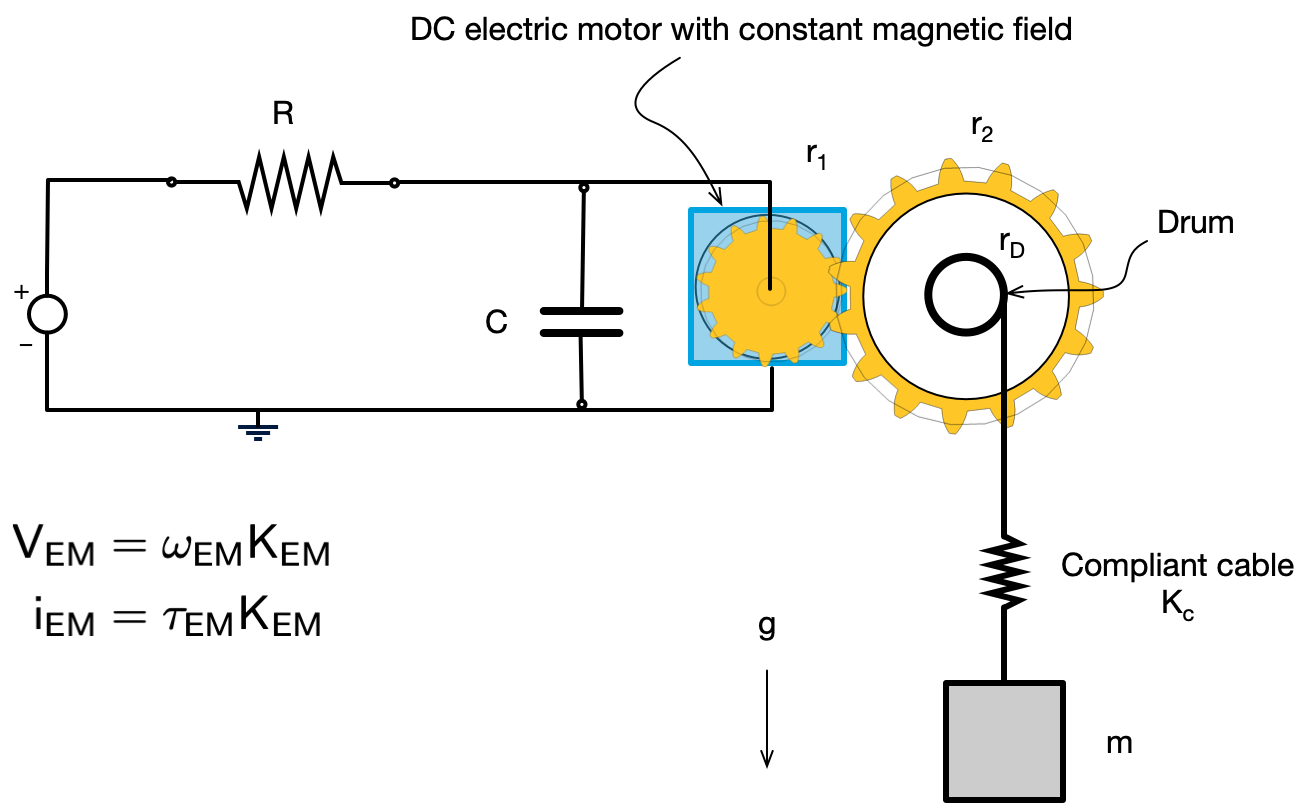

Linear Graph:

**N.B. ****Drum**** () is a ****mechanical transformer**

### Definitions

clear;
clc;
close all;
addpath('MBLibs/');

syms t;

N = 11; % Number of edges

% Across variables definition
syms V_s(t) V_R(t) V_C(t) V_em(t); % electrical side
syms w_em(t) w_gA(t) w_gB(t) w_dA(t) v_dB(t) v_k(t) v_m(t); % mechanical domain
            %   e1      e2    e3     e4     e5      e6      e7      e8     e9      e10     e11
alpha_vars  = [V_s(t) V_C(t) v_m(t) w_em(t) w_gB(t) v_dB(t) V_R(t) v_k(t) w_dA(t) w_gA(t) V_em(t)].'

$$alpha\_vars = \left(\begin{array}{c} V_{s}\left(t\right)\\ V_{C}\left(t\right)\\ v_{m}\left(t\right)\\ w_{\mathrm{em}}\left(t\right)\\ w_{\mathrm{gB}}\left(t\right)\\ v_{\mathrm{dB}}\left(t\right)\\ V_{R}\left(t\right)\\ v_{k}\left(t\right)\\ w_{\mathrm{dA}}\left(t\right)\\ w_{\mathrm{gA}}\left(t\right)\\ V_{\mathrm{em}}\left(t\right) \end{array}\right)$$

% Through var def
syms i_s(t) i_R(t) i_C(t) i_em(t); % Electrical side
syms T_em(t) T_gA(t) T_gB(t) T_dA(t) F_dB(t) F_k(t) F_m(t); % Mechanical domain
            %   e1      e2    e3     e4     e5      e6      e7      e8     e9      e10     e11
tau_vars    = [i_s(t) i_C(t) F_m(t) T_em(t) T_gB(t) F_dB(t) i_R(t) F_k(t) T_dA(t) T_gA(t) i_em(t)].'

$$tau\_vars = \left(\begin{array}{c} i_{s}\left(t\right)\\ i_{C}\left(t\right)\\ F_{m}\left(t\right)\\ T_{\mathrm{em}}\left(t\right)\\ T_{\mathrm{gB}}\left(t\right)\\ F_{\mathrm{dB}}\left(t\right)\\ i_{R}\left(t\right)\\ F_{k}\left(t\right)\\ T_{\mathrm{dA}}\left(t\right)\\ T_{\mathrm{gA}}\left(t\right)\\ i_{\mathrm{em}}\left(t\right) \end{array}\right)$$

### Constitutive equations

syms V_0 R C K_em r1 r2 r tau g m K_c
tau = r1/r2 % gear ratio of gear train

$$tau = \frac{r_{1}}{r_{2}}$$


eqns_const = [
    % Voltage source
    V_s == V_0;
    % Capacitor
    diff(V_C,t) == 1/C * i_C;
    % Mass (with added negative gravitational contribution
    diff(v_m,t) == 1/m * F_m - m*g;
    % Electric Motor (2 eqs)
    V_em == 1/K_em * w_em;  % a1 = 1/n * a2
    i_em == -K_em * T_em;   % t1 = -n * t2
    % Gear train (2 eqs)
    w_gA == 1/tau * w_gB;
    T_gA == -tau * T_gB;
    % Drum (2 eqs) --> Transforms torque and angular vel into force and linear vel
    w_dA == 1/r * v_dB;
    T_dA == -r * F_dB;
    % Resistor
    V_R == R * i_R;
    % Spring
    diff(F_k,t) == K_c * v_k;
]

$$eqns\_const(t) = \left(\begin{array}{c} V_{s}\left(t\right)=V_{0}\\ \frac{\partial }{\partial t}V_{C}\left(t\right)=\frac{i_{C}\left(t\right)}{C}\\ \frac{\partial }{\partial t}v_{m}\left(t\right)=\frac{F_{m}\left(t\right)}{m}-g\,m\\ V_{\mathrm{em}}\left(t\right)=\frac{w_{\mathrm{em}}\left(t\right)}{K_{\mathrm{em}}}\\ i_{\mathrm{em}}\left(t\right)=-K_{\mathrm{em}}\,T_{\mathrm{em}}\left(t\right)\\ w_{\mathrm{gA}}\left(t\right)=\frac{r_{2}\,w_{\mathrm{gB}}\left(t\right)}{r_{1}}\\ T_{\mathrm{gA}}\left(t\right)=-\frac{r_{1}\,T_{\mathrm{gB}}\left(t\right)}{r_{2}}\\ w_{\mathrm{dA}}\left(t\right)=\frac{v_{\mathrm{dB}}\left(t\right)}{r}\\ T_{\mathrm{dA}}\left(t\right)=-r\,F_{\mathrm{dB}}\left(t\right)\\ V_{R}\left(t\right)=R\,i_{R}\left(t\right)\\ \frac{\partial }{\partial t}F_{k}\left(t\right)=K_{c}\,v_{k}\left(t\right) \end{array}\right)$$

### Incidence Matrix

IM = [
%   e1  e2  e3  e4  e5  e6  e7  e8  e9  e10 e11
    1   0   0   0   0   0   -1  0   0   0   0   ;... N1
    0   1   0   0   0   0   1   0   0   0   1   ;... N2
    0   0   0   1   0   0   0   0   0   1   0   ;... N3
    0   0   0   0   1   0   0   0   1   0   0   ;... N4
    0   0   0   0   0   1   0   -1  0   0   0   ;... N5
    0   0   1   0   0   0   0   1   0   0   0   ;... N6
    -1  -1  0   0   0   0   0   0   0   0   -1  ;... Ge
    0   0   -1  -1  -1  -1  0   0  -1   -1  0   %   Gm
]

IM =      1     0     0     0     0     0    -1     0     0     0     0
     0     1     0     0     0     0     1     0     0     0     1
     0     0     0     1     0     0     0     0     0     1     0
     0     0     0     0     1     0     0     0     1     0     0
     0     0     0     0     0     1     0    -1     0     0     0
     0     0     1     0     0     0     0     1     0     0     0
    -1    -1     0     0     0     0     0     0     0     0    -1
     0     0    -1    -1    -1    -1     0     0    -1    -1     0



[nn, ne] = size(IM);
% CHECK: all the columns of IM have to sum to 0
sum_rows = 0;
for i=1:ne
    for j=1:nn
        sum_rows = sum_rows + IM(j,i);
    end
end
if ~(sum_rows==0)
    disp("Rows don't sum to 0, check the IM!!");
end

% Row reduced echelon form
rref(IM)

ans =      1     0     0     0     0     0    -1     0     0     0     0
     0     1     0     0     0     0     1     0     0     0     1
     0     0     1     0     0     0     0     1     0     0     0
     0     0     0     1     0     0     0     0     0     1     0
     0     0     0     0     1     0     0     0     1     0     0
     0     0     0     0     0     1     0    -1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0



nnsr = rank(IM)

nnsr = 6


% Dimensions
nb = nnsr; % #branches
nc = ne - nb;   % #chords

**A matrix**

A = sym(IM(1:nb, 1:ne))

$$A = \left(\begin{array}{ccccccccccc} 1 & 0 & 0 & 0 & 0 & 0 & -1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & -1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 \end{array}\right)$$

Af = rref(A)

$$Af = \left(\begin{array}{ccccccccccc} 1 & 0 & 0 & 0 & 0 & 0 & -1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 1\\ 0 & 0 & 1 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & -1 & 0 & 0 & 0 \end{array}\right)$$

Ac = Af(:, nb+1:end)

$$Ac = \left(\begin{array}{ccccc} -1 & 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 1\\ 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & -1 & 0 & 0 & 0 \end{array}\right)$$

% CHECK
Ib = Af(:, 1:nb)

$$Ib = \left(\begin{array}{cccccc} 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

**B matrix**

Bf = null(Af).'

$$Bf = \left(\begin{array}{ccccccccccc} 1 & -1 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 1 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & -1 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & -1 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

% CHECK
Af*Bf.'

$$ans = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

Bb = -Ac'

$$Bb = \left(\begin{array}{cccccc} 1 & -1 & 0 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & -1 & 0\\ 0 & 0 & 0 & -1 & 0 & 0\\ 0 & -1 & 0 & 0 & 0 & 0 \end{array}\right)$$

### Loop and node equations

Node

node_eqns = tau_vars(1:nb) == -Ac * tau_vars(nb+1:ne)

$$node\_eqns = \left(\begin{array}{c} i_{s}\left(t\right)=i_{R}\left(t\right)\\ i_{C}\left(t\right)=-i_{R}\left(t\right)-i_{\mathrm{em}}\left(t\right)\\ F_{m}\left(t\right)=-F_{k}\left(t\right)\\ T_{\mathrm{em}}\left(t\right)=-T_{\mathrm{gA}}\left(t\right)\\ T_{\mathrm{gB}}\left(t\right)=-T_{\mathrm{dA}}\left(t\right)\\ F_{\mathrm{dB}}\left(t\right)=F_{k}\left(t\right) \end{array}\right)$$

Loop

loop_eqns = alpha_vars(nb+1:ne) == -Bb * alpha_vars(1:nb)

$$loop\_eqns = \left(\begin{array}{c} V_{R}\left(t\right)=V_{C}\left(t\right)-V_{s}\left(t\right)\\ v_{k}\left(t\right)=v_{m}\left(t\right)-v_{\mathrm{dB}}\left(t\right)\\ w_{\mathrm{dA}}\left(t\right)=w_{\mathrm{gB}}\left(t\right)\\ w_{\mathrm{gA}}\left(t\right)=w_{\mathrm{em}}\left(t\right)\\ V_{\mathrm{em}}\left(t\right)=V_{C}\left(t\right) \end{array}\right)$$

### DAE system of equations

% Dependent vars
qvars_d = [lhs(node_eqns); lhs(loop_eqns)]

$$qvars\_d = \left(\begin{array}{c} i_{s}\left(t\right)\\ i_{C}\left(t\right)\\ F_{m}\left(t\right)\\ T_{\mathrm{em}}\left(t\right)\\ T_{\mathrm{gB}}\left(t\right)\\ F_{\mathrm{dB}}\left(t\right)\\ V_{R}\left(t\right)\\ v_{k}\left(t\right)\\ w_{\mathrm{dA}}\left(t\right)\\ w_{\mathrm{gA}}\left(t\right)\\ V_{\mathrm{em}}\left(t\right) \end{array}\right)$$

% Indep set of DAE vars
allvars = [alpha_vars; tau_vars];
dae_vars = setdiff(allvars, qvars_d)

$$dae\_vars = \left(\begin{array}{c} F_{k}\left(t\right)\\ T_{\mathrm{dA}}\left(t\right)\\ T_{\mathrm{gA}}\left(t\right)\\ V_{C}\left(t\right)\\ V_{s}\left(t\right)\\ i_{R}\left(t\right)\\ i_{\mathrm{em}}\left(t\right)\\ v_{\mathrm{dB}}\left(t\right)\\ v_{m}\left(t\right)\\ w_{\mathrm{em}}\left(t\right)\\ w_{\mathrm{gB}}\left(t\right) \end{array}\right)$$

#### Assembling equations

tmp = subs(eqns_const, lhs(loop_eqns), rhs(loop_eqns));
dae_eqns = subs(tmp, lhs(node_eqns), rhs(node_eqns))

$$dae\_eqns(t) = \left(\begin{array}{c} V_{s}\left(t\right)=V_{0}\\ \frac{\partial }{\partial t}V_{C}\left(t\right)=-\frac{i_{R}\left(t\right)+i_{\mathrm{em}}\left(t\right)}{C}\\ \frac{\partial }{\partial t}v_{m}\left(t\right)=-g\,m-\frac{F_{k}\left(t\right)}{m}\\ V_{C}\left(t\right)=\frac{w_{\mathrm{em}}\left(t\right)}{K_{\mathrm{em}}}\\ i_{\mathrm{em}}\left(t\right)=K_{\mathrm{em}}\,T_{\mathrm{gA}}\left(t\right)\\ w_{\mathrm{em}}\left(t\right)=\frac{r_{2}\,w_{\mathrm{gB}}\left(t\right)}{r_{1}}\\ T_{\mathrm{gA}}\left(t\right)=\frac{r_{1}\,T_{\mathrm{dA}}\left(t\right)}{r_{2}}\\ w_{\mathrm{gB}}\left(t\right)=\frac{v_{\mathrm{dB}}\left(t\right)}{r}\\ T_{\mathrm{dA}}\left(t\right)=-r\,F_{k}\left(t\right)\\ V_{C}\left(t\right)-V_{s}\left(t\right)=R\,i_{R}\left(t\right)\\ \frac{\partial }{\partial t}F_{k}\left(t\right)=-K_{c}\,\left(v_{\mathrm{dB}}\left(t\right)-v_{m}\left(t\right)\right) \end{array}\right)$$

### EQs manipulation: index reducion

Mass matrix form

[E_mat, G_vec] = massMatrixForm(dae_eqns,dae_vars)

$$E\_mat = \left(\begin{array}{ccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$G\_vec = \left(\begin{array}{c} V_{0}-V_{s}\left(t\right)\\ -\frac{i_{R}\left(t\right)+i_{\mathrm{em}}\left(t\right)}{C}\\ -g\,m-\frac{F_{k}\left(t\right)}{m}\\ \frac{w_{\mathrm{em}}\left(t\right)}{K_{\mathrm{em}}}-V_{C}\left(t\right)\\ K_{\mathrm{em}}\,T_{\mathrm{gA}}\left(t\right)-i_{\mathrm{em}}\left(t\right)\\ \frac{r_{2}\,w_{\mathrm{gB}}\left(t\right)}{r_{1}}-w_{\mathrm{em}}\left(t\right)\\ \frac{r_{1}\,T_{\mathrm{dA}}\left(t\right)}{r_{2}}-T_{\mathrm{gA}}\left(t\right)\\ \frac{v_{\mathrm{dB}}\left(t\right)}{r}-w_{\mathrm{gB}}\left(t\right)\\ -T_{\mathrm{dA}}\left(t\right)-r\,F_{k}\left(t\right)\\ V_{s}\left(t\right)-V_{C}\left(t\right)+R\,i_{R}\left(t\right)\\ -K_{c}\,\left(v_{\mathrm{dB}}\left(t\right)-v_{m}\left(t\right)\right) \end{array}\right)$$

Sorted E_mat and G_vec via dmperm

[p,q, ~,~,~,~] = dmperm(double(E_mat));
E_sorted = E_mat(p, :)

$$E\_sorted = \left(\begin{array}{ccccccccccc} 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

G_sorted = G_vec(p)

$$G\_sorted = \left(\begin{array}{c} -K_{c}\,\left(v_{\mathrm{dB}}\left(t\right)-v_{m}\left(t\right)\right)\\ -\frac{i_{R}\left(t\right)+i_{\mathrm{em}}\left(t\right)}{C}\\ -g\,m-\frac{F_{k}\left(t\right)}{m}\\ V_{0}-V_{s}\left(t\right)\\ \frac{w_{\mathrm{em}}\left(t\right)}{K_{\mathrm{em}}}-V_{C}\left(t\right)\\ K_{\mathrm{em}}\,T_{\mathrm{gA}}\left(t\right)-i_{\mathrm{em}}\left(t\right)\\ \frac{r_{2}\,w_{\mathrm{gB}}\left(t\right)}{r_{1}}-w_{\mathrm{em}}\left(t\right)\\ \frac{r_{1}\,T_{\mathrm{dA}}\left(t\right)}{r_{2}}-T_{\mathrm{gA}}\left(t\right)\\ \frac{v_{\mathrm{dB}}\left(t\right)}{r}-w_{\mathrm{gB}}\left(t\right)\\ -T_{\mathrm{dA}}\left(t\right)-r\,F_{k}\left(t\right)\\ V_{s}\left(t\right)-V_{C}\left(t\right)+R\,i_{R}\left(t\right) \end{array}\right)$$

Sorted system of DAE

n_ode = rank(E_sorted)

n_ode = 3


dae_vars_sorted = flip(dae_vars(q))

$$dae\_vars\_sorted = \left(\begin{array}{c} v_{m}\left(t\right)\\ V_{C}\left(t\right)\\ F_{k}\left(t\right)\\ w_{\mathrm{gB}}\left(t\right)\\ w_{\mathrm{em}}\left(t\right)\\ v_{\mathrm{dB}}\left(t\right)\\ i_{\mathrm{em}}\left(t\right)\\ i_{R}\left(t\right)\\ V_{s}\left(t\right)\\ T_{\mathrm{gA}}\left(t\right)\\ T_{\mathrm{dA}}\left(t\right) \end{array}\right)$$


eqns_sorted = E_sorted*diff(dae_vars_sorted,t)==G_sorted

$$eqns\_sorted = \left(\begin{array}{c} \frac{\partial }{\partial t}v_{m}\left(t\right)=-K_{c}\,\left(v_{\mathrm{dB}}\left(t\right)-v_{m}\left(t\right)\right)\\ \frac{\partial }{\partial t}w_{\mathrm{gB}}\left(t\right)=-\frac{i_{R}\left(t\right)+i_{\mathrm{em}}\left(t\right)}{C}\\ \frac{\partial }{\partial t}V_{s}\left(t\right)=-g\,m-\frac{F_{k}\left(t\right)}{m}\\ 0=V_{0}-V_{s}\left(t\right)\\ 0=\frac{w_{\mathrm{em}}\left(t\right)}{K_{\mathrm{em}}}-V_{C}\left(t\right)\\ 0=K_{\mathrm{em}}\,T_{\mathrm{gA}}\left(t\right)-i_{\mathrm{em}}\left(t\right)\\ 0=\frac{r_{2}\,w_{\mathrm{gB}}\left(t\right)}{r_{1}}-w_{\mathrm{em}}\left(t\right)\\ 0=\frac{r_{1}\,T_{\mathrm{dA}}\left(t\right)}{r_{2}}-T_{\mathrm{gA}}\left(t\right)\\ 0=\frac{v_{\mathrm{dB}}\left(t\right)}{r}-w_{\mathrm{gB}}\left(t\right)\\ 0=-T_{\mathrm{dA}}\left(t\right)-r\,F_{k}\left(t\right)\\ 0=V_{s}\left(t\right)-V_{C}\left(t\right)+R\,i_{R}\left(t\right) \end{array}\right)$$

Extract the first n_ode equations

ode_eqns = eqns_sorted(1:n_ode)

$$ode\_eqns = \left(\begin{array}{c} \frac{\partial }{\partial t}v_{m}\left(t\right)=-K_{c}\,\left(v_{\mathrm{dB}}\left(t\right)-v_{m}\left(t\right)\right)\\ \frac{\partial }{\partial t}w_{\mathrm{gB}}\left(t\right)=-\frac{i_{R}\left(t\right)+i_{\mathrm{em}}\left(t\right)}{C}\\ \frac{\partial }{\partial t}V_{s}\left(t\right)=-g\,m-\frac{F_{k}\left(t\right)}{m} \end{array}\right)$$

Vector of differential variables

ode_vars = get_ode_vars(dae_vars, ode_eqns)

$$ode\_vars = \left(\begin{array}{c} v_{m}\left(t\right)\\ w_{\mathrm{gB}}\left(t\right)\\ V_{s}\left(t\right) \end{array}\right)$$

Vector of algebraic variables

alg_vars = setdiff(dae_vars, ode_vars)

$$alg\_vars = \left(\begin{array}{c} F_{k}\left(t\right)\\ T_{\mathrm{dA}}\left(t\right)\\ T_{\mathrm{gA}}\left(t\right)\\ V_{C}\left(t\right)\\ i_{R}\left(t\right)\\ i_{\mathrm{em}}\left(t\right)\\ v_{\mathrm{dB}}\left(t\right)\\ w_{\mathrm{em}}\left(t\right) \end{array}\right)$$

Algebraic equations

alg_eqns = eqns_sorted(n_ode+1:end)

$$alg\_eqns = \left(\begin{array}{c} 0=V_{0}-V_{s}\left(t\right)\\ 0=\frac{w_{\mathrm{em}}\left(t\right)}{K_{\mathrm{em}}}-V_{C}\left(t\right)\\ 0=K_{\mathrm{em}}\,T_{\mathrm{gA}}\left(t\right)-i_{\mathrm{em}}\left(t\right)\\ 0=\frac{r_{2}\,w_{\mathrm{gB}}\left(t\right)}{r_{1}}-w_{\mathrm{em}}\left(t\right)\\ 0=\frac{r_{1}\,T_{\mathrm{dA}}\left(t\right)}{r_{2}}-T_{\mathrm{gA}}\left(t\right)\\ 0=\frac{v_{\mathrm{dB}}\left(t\right)}{r}-w_{\mathrm{gB}}\left(t\right)\\ 0=-T_{\mathrm{dA}}\left(t\right)-r\,F_{k}\left(t\right)\\ 0=V_{s}\left(t\right)-V_{C}\left(t\right)+R\,i_{R}\left(t\right) \end{array}\right)$$

### Numerical solution

System is index-1 so we can try to solve the linear algebraic equations and subs tthe solutions into the DAEs

syms y [length(alg_vars),1]
tmp = subs(alg_eqns, alg_vars, y)

$$tmp = \left(\begin{array}{c} 0=V_{0}-V_{s}\left(t\right)\\ 0=\frac{y_{8}}{K_{\mathrm{em}}}-y_{4}\\ 0=K_{\mathrm{em}}\,y_{3}-y_{6}\\ 0=\frac{r_{2}\,w_{\mathrm{gB}}\left(t\right)}{r_{1}}-y_{8}\\ 0=\frac{r_{1}\,y_{2}}{r_{2}}-y_{3}\\ 0=\frac{y_{7}}{r}-w_{\mathrm{gB}}\left(t\right)\\ 0=-y_{2}-r\,y_{1}\\ 0=V_{s}\left(t\right)-y_{4}+R\,y_{5} \end{array}\right)$$

sol_alg = solve(tmp, y, 'ReturnConditions', true)

sol_alg = struct with fields:
            y1: [0×1 sym]
            y2: [0×1 sym]
            y3: [0×1 sym]
            y4: [0×1 sym]
            y5: [0×1 sym]
            y6: [0×1 sym]
            y7: [0×1 sym]
            y8: [0×1 sym]
    parameters: [1×0 sym]
    conditions: [0×1 sym]


## EX3 - Exam 22/06/2026

### Definitions

clear;
clc;
close all;

addpath('MBLibs')

syms t;

% N = 9; % number of edges

% Through variables
syms F_mL(t) F_mW(t) Q_c(t) F_cL(t) F_cW(t) F_ks(t) Q_R(t) F_p(t) F_L(t)
% Across vars
syms v_mL(t) v_mW(t) P_c(t) v_cL(t) v_cW(t) v_ks(t) P_R(t) v_p(t) v_L(t)

%            e1      e2      e3      e4      e5      e6      e7      e8      e9
tau_vars =  [F_mL(t) F_mW(t) Q_c(t) F_cL(t) F_cW(t) F_ks(t) Q_R(t) F_p(t) F_L(t)].'

$$tau\_vars = \left(\begin{array}{c} F_{\mathrm{mL}}\left(t\right)\\ F_{\mathrm{mW}}\left(t\right)\\ Q_{c}\left(t\right)\\ F_{\mathrm{cL}}\left(t\right)\\ F_{\mathrm{cW}}\left(t\right)\\ F_{\mathrm{ks}}\left(t\right)\\ Q_{R}\left(t\right)\\ F_{p}\left(t\right)\\ F_{L}\left(t\right) \end{array}\right)$$

%            e1      e2      e3      e4      e5      e6      e7      e8      e9
alpha_vars= [v_mL(t) v_mW(t) P_c(t) v_cL(t) v_cW(t) v_ks(t) P_R(t) v_p(t) v_L(t)].'

$$alpha\_vars = \left(\begin{array}{c} v_{\mathrm{mL}}\left(t\right)\\ v_{\mathrm{mW}}\left(t\right)\\ P_{c}\left(t\right)\\ v_{\mathrm{cL}}\left(t\right)\\ v_{\mathrm{cW}}\left(t\right)\\ v_{\mathrm{ks}}\left(t\right)\\ P_{R}\left(t\right)\\ v_{p}\left(t\right)\\ v_{L}\left(t\right) \end{array}\right)$$

### Constitutive equations

syms mL mW A_c cL cW ks R F_0

eqns_const = [
    % Mass mL
    diff(v_mL,t) == 1/mL * F_mL;
    % Mass mW
    diff(v_mW,t) == 1/mW * F_mW;
    % Coupler
    Q_c == A_c * v_p;
    F_p == A_c * P_c;
    % Rolling friction model: Dampers cL and cW
    F_cL == cL * v_cL;
    F_cW == cW * v_cW;
    % Spring
    diff(F_ks,t) == ks * v_ks;
    % Fluid resistor
    P_R == R * Q_R;
    % Force source
    F_L == F_0
]

$$eqns\_const(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}v_{\mathrm{mL}}\left(t\right)=\frac{F_{\mathrm{mL}}\left(t\right)}{\mathrm{mL}}\\ \frac{\partial }{\partial t}v_{\mathrm{mW}}\left(t\right)=\frac{F_{\mathrm{mW}}\left(t\right)}{\mathrm{mW}}\\ Q_{c}\left(t\right)=A_{c}\,v_{p}\left(t\right)\\ F_{p}\left(t\right)=A_{c}\,P_{c}\left(t\right)\\ F_{\mathrm{cL}}\left(t\right)=\mathrm{cL}\,v_{\mathrm{cL}}\left(t\right)\\ F_{\mathrm{cW}}\left(t\right)=\mathrm{cW}\,v_{\mathrm{cW}}\left(t\right)\\ \frac{\partial }{\partial t}F_{\mathrm{ks}}\left(t\right)=\mathrm{ks}\,v_{\mathrm{ks}}\left(t\right)\\ P_{R}\left(t\right)=R\,Q_{R}\left(t\right)\\ F_{L}\left(t\right)=F_{0} \end{array}\right)$$

### Incidence matrix

IM = [
%   e1  e2  e3  e4  e5  e6  e7  e8  e9    
    1   0   0   1   0   1  0   -1  1   ;... % N1
    0   1   0   0   1   -1   0   1   0   ;... % N2
    0   0   -1  0   0   0   -1  0   0   ;... % N3
    0   0   1   0   0   0   1   0   0   ;... % N4
    -1  -1  0   -1  -1  0   0   0   -1       % G
]

IM =      1     0     0     1     0     1     0    -1     1
     0     1     0     0     1    -1     0     1     0
     0     0    -1     0     0     0    -1     0     0
     0     0     1     0     0     0     1     0     0
    -1    -1     0    -1    -1     0     0     0    -1



[nn, ne] = size(IM);

rref(IM)

ans =      1     0     0     1     0     1     0    -1     1
     0     1     0     0     1    -1     0     1     0
     0     0     1     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0



nnsr = rank(IM)

nnsr = 3


% Branches
nb = nnsr

nb = 3

% Chords
nc = ne - nb

nc = 6

A matrix

A = sym(IM(1:nb, 1:ne))

$$A = \left(\begin{array}{ccccccccc} 1 & 0 & 0 & 1 & 0 & 1 & 0 & -1 & 1\\ 0 & 1 & 0 & 0 & 1 & -1 & 0 & 1 & 0\\ 0 & 0 & -1 & 0 & 0 & 0 & -1 & 0 & 0 \end{array}\right)$$


Af = rref(A)

$$Af = \left(\begin{array}{ccccccccc} 1 & 0 & 0 & 1 & 0 & 1 & 0 & -1 & 1\\ 0 & 1 & 0 & 0 & 1 & -1 & 0 & 1 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 & 1 & 0 & 0 \end{array}\right)$$


Ac = Af(:, nb+1:end)

$$Ac = \left(\begin{array}{cccccc} 1 & 0 & 1 & 0 & -1 & 1\\ 0 & 1 & -1 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 \end{array}\right)$$

B matrix

Bf = null(Af).'

$$Bf = \left(\begin{array}{ccccccccc} -1 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & -1 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ -1 & 1 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 0 & 1 & 0 & 0\\ 1 & -1 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

Bb = -Ac'

$$Bb = \left(\begin{array}{ccc} -1 & 0 & 0\\ 0 & -1 & 0\\ -1 & 1 & 0\\ 0 & 0 & -1\\ 1 & -1 & 0\\ -1 & 0 & 0 \end{array}\right)$$

#### Node and loop equations

node_eqns = tau_vars(1:nb) == -Ac * tau_vars(nb+1:end)

$$node\_eqns = \left(\begin{array}{c} F_{\mathrm{mL}}\left(t\right)=F_{p}\left(t\right)-F_{\mathrm{cL}}\left(t\right)-F_{\mathrm{ks}}\left(t\right)-F_{L}\left(t\right)\\ F_{\mathrm{mW}}\left(t\right)=F_{\mathrm{ks}}\left(t\right)-F_{\mathrm{cW}}\left(t\right)-F_{p}\left(t\right)\\ Q_{c}\left(t\right)=-Q_{R}\left(t\right) \end{array}\right)$$

loop_eqns = alpha_vars(nb+1:end) == -Bb * alpha_vars(1:nb)

$$loop\_eqns = \left(\begin{array}{c} v_{\mathrm{cL}}\left(t\right)=v_{\mathrm{mL}}\left(t\right)\\ v_{\mathrm{cW}}\left(t\right)=v_{\mathrm{mW}}\left(t\right)\\ v_{\mathrm{ks}}\left(t\right)=v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\\ P_{R}\left(t\right)=P_{c}\left(t\right)\\ v_{p}\left(t\right)=v_{\mathrm{mW}}\left(t\right)-v_{\mathrm{mL}}\left(t\right)\\ v_{L}\left(t\right)=v_{\mathrm{mL}}\left(t\right) \end{array}\right)$$

### DAE system of equations

% Dependent variables
qvars_d = [lhs(node_eqns); lhs(loop_eqns)]

$$qvars\_d = \left(\begin{array}{c} F_{\mathrm{mL}}\left(t\right)\\ F_{\mathrm{mW}}\left(t\right)\\ Q_{c}\left(t\right)\\ v_{\mathrm{cL}}\left(t\right)\\ v_{\mathrm{cW}}\left(t\right)\\ v_{\mathrm{ks}}\left(t\right)\\ P_{R}\left(t\right)\\ v_{p}\left(t\right)\\ v_{L}\left(t\right) \end{array}\right)$$


% Independent vars
allvars = [alpha_vars; tau_vars];
dae_vars = setdiff(allvars, qvars_d)

$$dae\_vars = \left(\begin{array}{c} F_{L}\left(t\right)\\ F_{\mathrm{cL}}\left(t\right)\\ F_{\mathrm{cW}}\left(t\right)\\ F_{\mathrm{ks}}\left(t\right)\\ F_{p}\left(t\right)\\ P_{c}\left(t\right)\\ Q_{R}\left(t\right)\\ v_{\mathrm{mL}}\left(t\right)\\ v_{\mathrm{mW}}\left(t\right) \end{array}\right)$$

### Assembling and solving equations

tmp = subs(eqns_const, lhs(node_eqns), rhs(node_eqns));
dae_eqns = subs(tmp, lhs(loop_eqns), rhs(loop_eqns))

$$dae\_eqns(t) = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}v_{\mathrm{mL}}\left(t\right)=-\frac{F_{L}\left(t\right)+F_{\mathrm{cL}}\left(t\right)+F_{\mathrm{ks}}\left(t\right)-F_{p}\left(t\right)}{\mathrm{mL}}\\ \frac{\partial }{\partial t}v_{\mathrm{mW}}\left(t\right)=-\frac{F_{\mathrm{cW}}\left(t\right)-F_{\mathrm{ks}}\left(t\right)+F_{p}\left(t\right)}{\mathrm{mW}}\\ -Q_{R}\left(t\right)=-A_{c}\,\sigma_{1}\\ F_{p}\left(t\right)=A_{c}\,P_{c}\left(t\right)\\ F_{\mathrm{cL}}\left(t\right)=\mathrm{cL}\,v_{\mathrm{mL}}\left(t\right)\\ F_{\mathrm{cW}}\left(t\right)=\mathrm{cW}\,v_{\mathrm{mW}}\left(t\right)\\ \frac{\partial }{\partial t}F_{\mathrm{ks}}\left(t\right)=\mathrm{ks}\,\sigma_{1}\\ P_{c}\left(t\right)=R\,Q_{R}\left(t\right)\\ F_{L}\left(t\right)=F_{0} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right) \end{array}$$

### Index reduction

[E_mat, G_vec] = massMatrixForm(dae_eqns, dae_vars)

$$E\_mat = \left(\begin{array}{ccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$G\_vec = \begin{array}{l} \left(\begin{array}{c} -\frac{F_{L}\left(t\right)+F_{\mathrm{cL}}\left(t\right)+F_{\mathrm{ks}}\left(t\right)-F_{p}\left(t\right)}{\mathrm{mL}}\\ -\frac{F_{\mathrm{cW}}\left(t\right)-F_{\mathrm{ks}}\left(t\right)+F_{p}\left(t\right)}{\mathrm{mW}}\\ Q_{R}\left(t\right)-A_{c}\,\sigma_{1}\\ A_{c}\,P_{c}\left(t\right)-F_{p}\left(t\right)\\ \mathrm{cL}\,v_{\mathrm{mL}}\left(t\right)-F_{\mathrm{cL}}\left(t\right)\\ \mathrm{cW}\,v_{\mathrm{mW}}\left(t\right)-F_{\mathrm{cW}}\left(t\right)\\ \mathrm{ks}\,\sigma_{1}\\ R\,Q_{R}\left(t\right)-P_{c}\left(t\right)\\ F_{0}-F_{L}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right) \end{array}$$

Reordering the equations using DM permutation

[p,q,~,~,~,~] = dmperm(double(E_mat));
E_sorted = E_mat(p, :)

$$E\_sorted = \left(\begin{array}{ccccccccc} 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

G_sorted = G_vec(p);

eqns_sorted = E_sorted*diff(dae_vars) == G_sorted

$$eqns\_sorted = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}F_{\mathrm{ks}}\left(t\right)=\mathrm{ks}\,\sigma_{1}\\ \frac{\partial }{\partial t}v_{\mathrm{mL}}\left(t\right)=-\frac{F_{L}\left(t\right)+F_{\mathrm{cL}}\left(t\right)+F_{\mathrm{ks}}\left(t\right)-F_{p}\left(t\right)}{\mathrm{mL}}\\ \frac{\partial }{\partial t}v_{\mathrm{mW}}\left(t\right)=-\frac{F_{\mathrm{cW}}\left(t\right)-F_{\mathrm{ks}}\left(t\right)+F_{p}\left(t\right)}{\mathrm{mW}}\\ 0=Q_{R}\left(t\right)-A_{c}\,\sigma_{1}\\ 0=A_{c}\,P_{c}\left(t\right)-F_{p}\left(t\right)\\ 0=\mathrm{cL}\,v_{\mathrm{mL}}\left(t\right)-F_{\mathrm{cL}}\left(t\right)\\ 0=\mathrm{cW}\,v_{\mathrm{mW}}\left(t\right)-F_{\mathrm{cW}}\left(t\right)\\ 0=R\,Q_{R}\left(t\right)-P_{c}\left(t\right)\\ 0=F_{0}-F_{L}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right) \end{array}$$

Extracting ODE eqns

n_ode = rank(E_sorted)

n_ode = 3

ode_eqns = eqns_sorted(1:n_ode)

$$ode\_eqns = \left(\begin{array}{c} \frac{\partial }{\partial t}F_{\mathrm{ks}}\left(t\right)=\mathrm{ks}\,\left(v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\right)\\ \frac{\partial }{\partial t}v_{\mathrm{mL}}\left(t\right)=-\frac{F_{L}\left(t\right)+F_{\mathrm{cL}}\left(t\right)+F_{\mathrm{ks}}\left(t\right)-F_{p}\left(t\right)}{\mathrm{mL}}\\ \frac{\partial }{\partial t}v_{\mathrm{mW}}\left(t\right)=-\frac{F_{\mathrm{cW}}\left(t\right)-F_{\mathrm{ks}}\left(t\right)+F_{p}\left(t\right)}{\mathrm{mW}} \end{array}\right)$$

ode_vars = get_ode_vars(dae_vars, ode_eqns)

$$ode\_vars = \left(\begin{array}{c} F_{\mathrm{ks}}\left(t\right)\\ v_{\mathrm{mL}}\left(t\right)\\ v_{\mathrm{mW}}\left(t\right) \end{array}\right)$$

Extracting algebraic equations

alg_vars = setdiff(dae_vars, ode_vars)

$$alg\_vars = \left(\begin{array}{c} F_{L}\left(t\right)\\ F_{\mathrm{cL}}\left(t\right)\\ F_{\mathrm{cW}}\left(t\right)\\ F_{p}\left(t\right)\\ P_{c}\left(t\right)\\ Q_{R}\left(t\right) \end{array}\right)$$

alg_eqns = eqns_sorted(n_ode+1:end)

$$alg\_eqns = \left(\begin{array}{c} 0=Q_{R}\left(t\right)-A_{c}\,\left(v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\right)\\ 0=A_{c}\,P_{c}\left(t\right)-F_{p}\left(t\right)\\ 0=\mathrm{cL}\,v_{\mathrm{mL}}\left(t\right)-F_{\mathrm{cL}}\left(t\right)\\ 0=\mathrm{cW}\,v_{\mathrm{mW}}\left(t\right)-F_{\mathrm{cW}}\left(t\right)\\ 0=R\,Q_{R}\left(t\right)-P_{c}\left(t\right)\\ 0=F_{0}-F_{L}\left(t\right) \end{array}\right)$$

### Solution

syms y [length(alg_vars),1]
tmp = subs(alg_eqns, alg_vars, y)

$$tmp = \left(\begin{array}{c} 0=y_{6}-A_{c}\,\left(v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\right)\\ 0=A_{c}\,y_{5}-y_{4}\\ 0=\mathrm{cL}\,v_{\mathrm{mL}}\left(t\right)-y_{2}\\ 0=\mathrm{cW}\,v_{\mathrm{mW}}\left(t\right)-y_{3}\\ 0=R\,y_{6}-y_{5}\\ 0=F_{0}-y_{1} \end{array}\right)$$

alg_sol = solve(tmp, y)

alg_sol = struct with fields:
    y1: F_0
    y2: cL*v_mL(t)
    y3: cW*v_mW(t)
    y4: A_c^2*R*(v_mL(t) - v_mW(t))
    y5: A_c*R*(v_mL(t) - v_mW(t))
    y6: A_c*(v_mL(t) - v_mW(t))


Reduced ODE system:

reduced_ode = subs( subs(ode_eqns, alg_vars, y), alg_sol)

$$reduced\_ode = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}F_{\mathrm{ks}}\left(t\right)=\mathrm{ks}\,\left(v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\right)\\ \frac{\partial }{\partial t}v_{\mathrm{mL}}\left(t\right)=-\frac{-\sigma_{1}+F_{0}+F_{\mathrm{ks}}\left(t\right)+\mathrm{cL}\,v_{\mathrm{mL}}\left(t\right)}{\mathrm{mL}}\\ \frac{\partial }{\partial t}v_{\mathrm{mW}}\left(t\right)=-\frac{\sigma_{1}-F_{\mathrm{ks}}\left(t\right)+\mathrm{cW}\,v_{\mathrm{mW}}\left(t\right)}{\mathrm{mW}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R\,\left(v_{\mathrm{mL}}\left(t\right)-v_{\mathrm{mW}}\left(t\right)\right)\,{A_{c}}^{2} \end{array}$$

#### Data

% system data
data.mL  = 80e3; % kg
data.mW  = 50e3; % kg
data.ks = 1.5e6; % N/m
data.cL = 1.0e3; % Ns/m
data.cW = 0.8e3; % Ns/m
data.A_c  = 7.85e-3; % m^2
data.beta = 1.4e9; % bulk modulus  (Pa)
data.V_0  = 2*3.0e-3; % m^3
data.R    = -4e8; % Orifice discharge coefficient
%data.V0 = 24;
locomotive_thrust = -250e3*sin(atan(1*t));

% substitute data
ode_red = subs(subs(reduced_ode,data), F_0, locomotive_thrust)

$$ode\_red = \left(\begin{array}{c} \frac{\partial }{\partial t}F_{\mathrm{ks}}\left(t\right)=1500000\,v_{\mathrm{mL}}\left(t\right)-1500000\,v_{\mathrm{mW}}\left(t\right)\\ \frac{\partial }{\partial t}v_{\mathrm{mL}}\left(t\right)=\frac{24649\,v_{\mathrm{mW}}\left(t\right)}{80000}-\frac{25649\,v_{\mathrm{mL}}\left(t\right)}{80000}-\frac{F_{\mathrm{ks}}\left(t\right)}{80000}+\frac{25\,t}{8\,\sqrt{t^{2}+1}}\\ \frac{\partial }{\partial t}v_{\mathrm{mW}}\left(t\right)=\frac{F_{\mathrm{ks}}\left(t\right)}{50000}+\frac{24649\,v_{\mathrm{mL}}\left(t\right)}{50000}-\frac{25449\,v_{\mathrm{mW}}\left(t\right)}{50000} \end{array}\right)$$

#### Initial Conditions

[MM,FF] = massMatrixForm(ode_red, ode_vars);
ode_rhs = odeFunction(FF, ode_vars)

ode_rhs = function_handle with value:
    @(t,in2)[in2(2,:).*1.5e+6-in2(3,:).*1.5e+6;in2(1,:).*(-1.25e-5)-in2(2,:).*3.206125e-1+in2(3,:).*3.081125e-1+t.*1.0./sqrt(t.^2+1.0).*(2.5e+1./8.0);in2(1,:)./5.0e+4+in2(2,:).*4.9298e-1-in2(3,:).*5.0898e-1]



% Initial conditions on ODE vars
ics = [
    0.0;    % F_ks(0)
    0.0;    % v_mL(0)
    0.0     % v_mW(0)
]

ics =      0
     0
     0



tspan = [0, 5]; % simulation time span

Call Runge Kutta 45 solver

[tS, yS] = ode45(@(t,x)ode_rhs(t,x), tspan, ics);

Plots

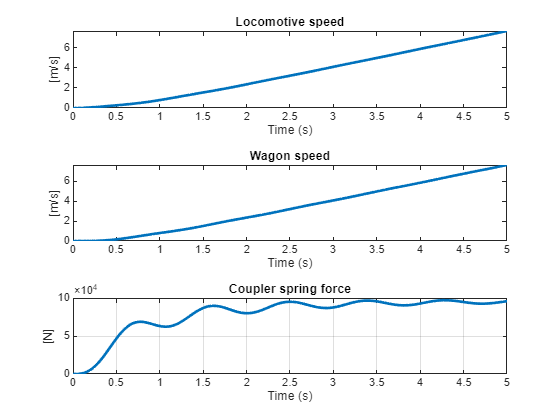

% Plot the results
figure;
tiledlayout(3,1)
nexttile
plot(tS, yS(:,2),'LineWidth',2);
xlabel('Time (s)');
ylabel('[m/s]');
title('Locomotive speed');

nexttile
plot(tS, yS(:,3),'LineWidth',2);
xlabel('Time (s)');
ylabel('[m/s]');
title('Wagon speed');

nexttile
plot(tS, yS(:,1),'LineWidth',2);
xlabel('Time (s)');
ylabel('[N]');
title('Coupler spring force');

grid on;